Aufgabe 1)

6)

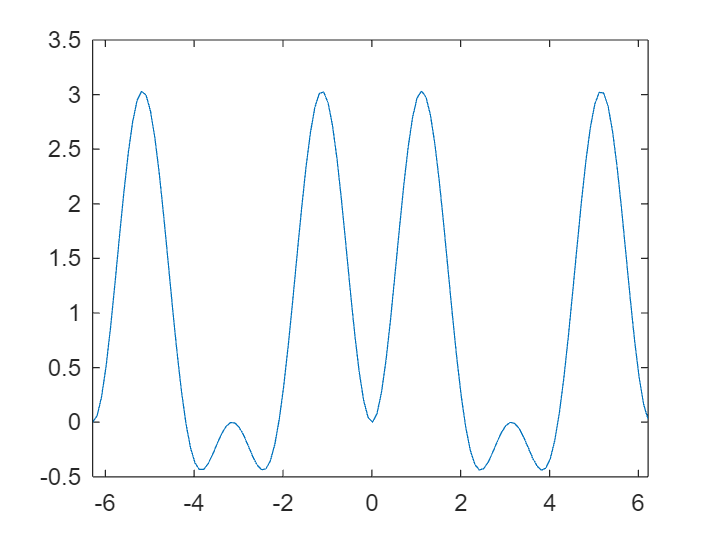

Fs = 1e+6; % [Hz]
df = 1000; % [Hz]
h = [1 1 -1 -1];
T = 1/Fs;
w = 2 * pi * Fs * T;
o = -w : 0.1 : w;
H = h(1) * exp(-1i*0*o) + h(2) * exp(-1i*1*o) + h(3) * exp(-1i*2*o) + h(4) * exp(-1i*3*o);

plot(o, real(H));

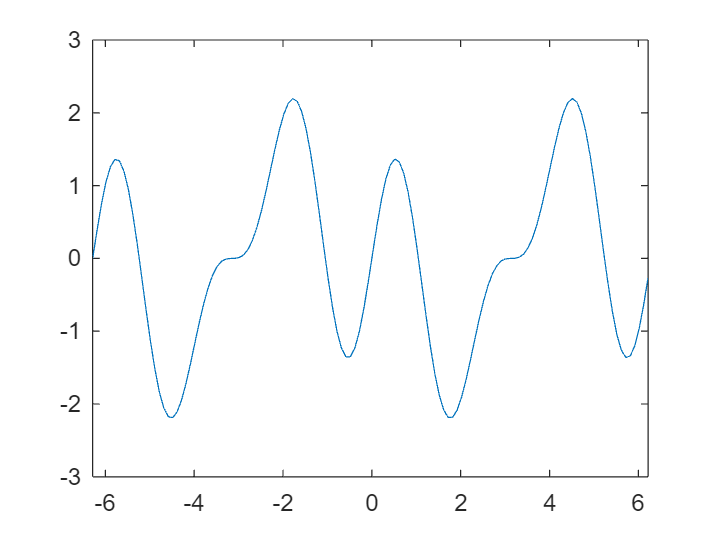

plot(o, imag(H));

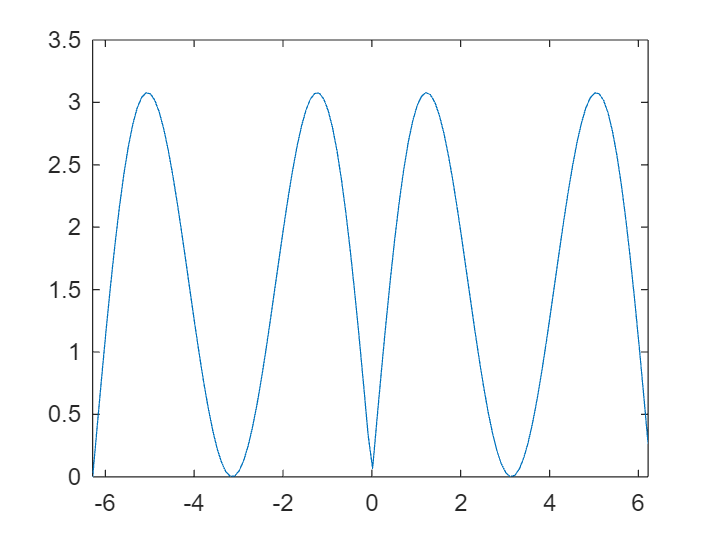

plot(o, abs(H));

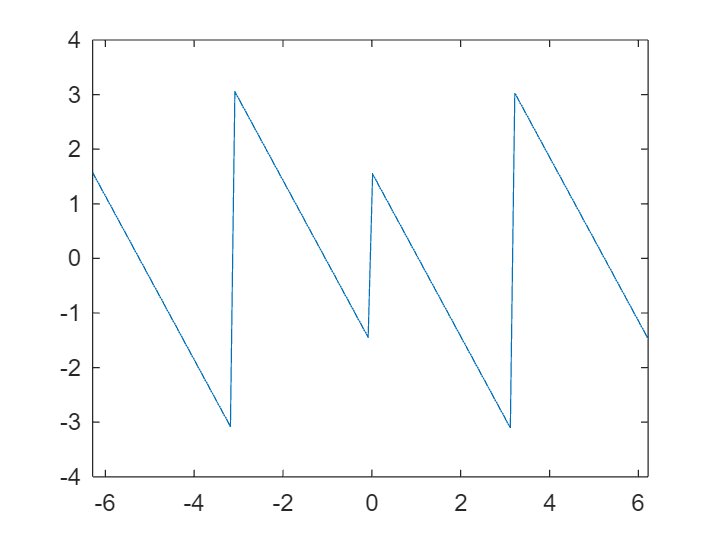

plot(o, angle(H));

7)

h1 = [1 1 -1 -1 zeros(1, 996)];
H1 = fft(h1);
H1 = [H1(501:end) H1(1:500)];
f = -500e3:Fs/1000:500e3-1;

9)

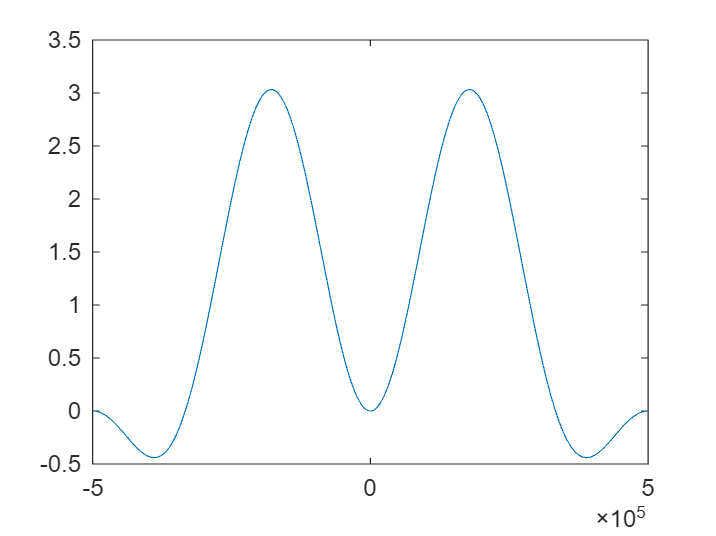

plot(f, real(H1));

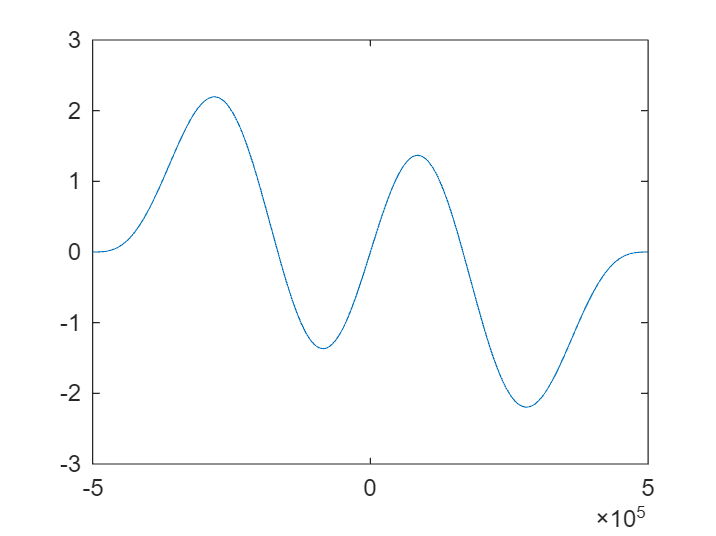

plot(f, imag(H1));

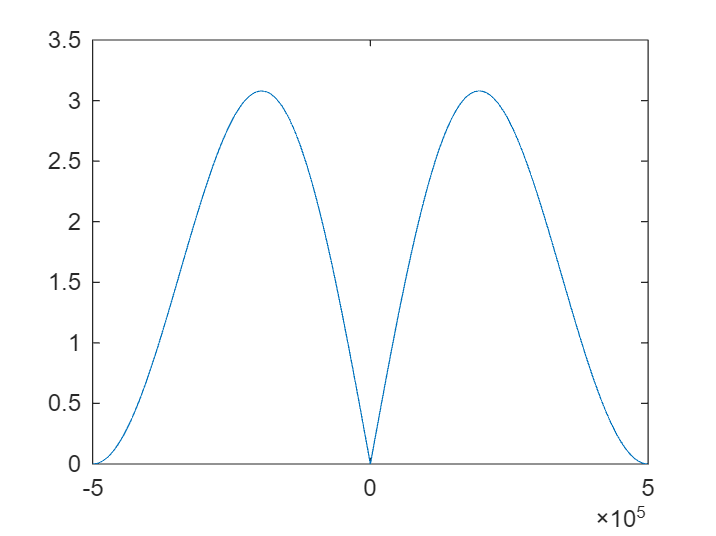

plot(f, abs(H1));

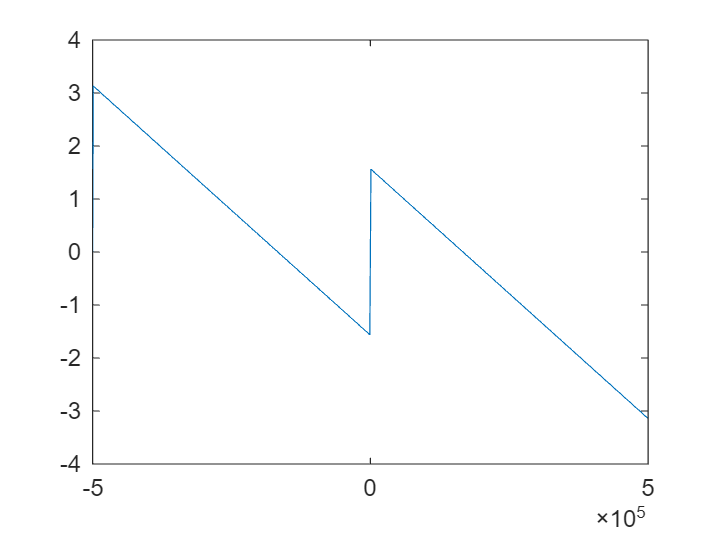

plot(f, angle(H1));

10)

Aufgabe 2)

g)

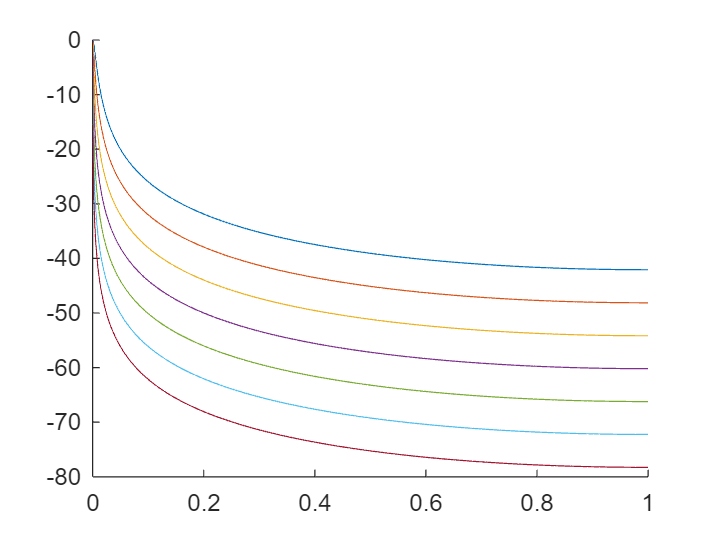

figure;
hold on;
w = logspace(-5,0, 1000);
for n = 6:12
    b0 = 2^-n;
    c = 1-b0;
    H = b0 ./ (1 - c * exp(-1i .* w .* pi));
    H_dB = 20 .* log10(abs(H));
    semilogx(w, H_dB);
end